1 

(a)

-pf-


$$IDFT\{X[k]\}=x[n]\\
=\frac{1}{N}\sum_{k=0}^{N-1}X[k]W_N^{-kn}\\
=\frac{1}{N}\sum_{r=1-N}^0X[-r]W_N^{rn}\\
=\frac{1}{N}\sum_{r=0}^{N-1}x[<-r>_N]W_N^{rn}\\
=\frac{1}{N}DFT\{X[<-k>_N]\}$$


(b) 

clc;clear;close all;

X=[1 2 3 4 5 6 7 8];
IDFT(fft(X),8) %test

ans =      1     2     3     4     5     6     7     8


2. 

(a)

clc;clear;close all;

W=dft_matrix(4) %test

W =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.0000 + 1.0000i  -1.0000 - 0.0000i   0.0000 - 1.0000i


(b)

x=[1 2 3 4] % Test whether dftdirect_m works

x =      1     2     3     4


W=dft_matrix(length(x));
X=dftdirect_m(x,W);
Y=fft(x);
%isequal(round(X.'),round(Y)) % True

tic
x=randn(1,128)+1j*randn(1,128);
W=dft_matrix(length(x));
X=dftdirect_m(x,W);
toc

Elapsed time is 0.023737 seconds.


tic
Y=dftdirect(x);
toc

Elapsed time is 0.028706 seconds.



tic
x=randn(1,256)+1j*randn(1,256);
W=dft_matrix(length(x));
X=dftdirect_m(x,W);
toc

Elapsed time is 0.090172 seconds.


tic
Y=dftdirect(x);
toc

Elapsed time is 0.038513 seconds.



tic
x=randn(1,512)+1j*randn(1,512);
W=dft_matrix(length(x));
X=dftdirect_m(x,W);
toc

Elapsed time is 0.225249 seconds.


tic
Y=dftdirect(x);
toc

Elapsed time is 0.277598 seconds.



tic
x=randn(1,1024)+1j*randn(1,1024);
W=dft_matrix(length(x));
X=dftdirect_m(x,W);
toc

Elapsed time is 1.020545 seconds.


tic
Y=dftdirect(x);
toc % the modified function, dftdirect_m(x,W), saves time when N>512.

Elapsed time is 1.953447 seconds.


(c)

x=[1 4 5 0] % Test whether dftrecur_m works

x =      1     4     5     0


W=dft_matrix(2);
X=fftrecur_m(x,W);
Y=fft(x);
%isequal(round(X.'),round(Y)) % True

tic
x=randn(1,128)+1j*randn(1,128);
W=dft_matrix(length(x));
X=fftrecur_m(x,W);
toc

Elapsed time is 0.029076 seconds.


tic
Y=fftrecur(x);
toc

Elapsed time is 0.012452 seconds.



tic
x=randn(1,256)+1j*randn(1,256);
W=dft_matrix(length(x));
X=fftrecur_m(x,W);
toc

Elapsed time is 0.078177 seconds.


tic
Y=fftrecur(x);
toc

Elapsed time is 0.010114 seconds.



tic
x=randn(1,512)+1j*randn(1,512);
W=dft_matrix(length(x));
X=fftrecur_m(x,W);
toc

Elapsed time is 0.242006 seconds.


tic
Y=fftrecur(x);
toc

Elapsed time is 0.016669 seconds.



tic
x=randn(1,1024)+1j*randn(1,1024);
W=dft_matrix(length(x));
X=fftrecur_m(x,W);
toc

Elapsed time is 0.985872 seconds.


tic
Y=fftrecur(x);
toc % the modified function, dftdirect_m(x,W), saves time when N>256.

Elapsed time is 0.021770 seconds.


3.

(a) See MATLAB code (一一列出太麻煩)

(b)

x=[0 1 2 2 3 3 3 4]

x =      0     1     2     2     3     3     3     4


X1=fft(x)

X1 =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


tic
X2=fftalt8(x)

X2 =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


toc

Elapsed time is 0.056842 seconds.


isequal(round(X1),round(X2)) % True

ans = logical
   1


(c)

tic
X3=fftditr2(x)

X3 =   18.0000 + 0.0000i  -0.7071 - 4.1213i   3.0000 - 4.0000i  -0.7071 - 0.7071i   8.0000 + 0.0000i   0.0000 - 2.0000i   3.0000 + 0.0000i   0.0000 + 0.0000i


toc

Elapsed time is 0.527050 seconds.


fftditr2因為使用了太多for迴圈效率降低，不如我們用fftalt8直接計算。

4.

(b)

x=randn(1,512)+1j*randn(1,512); % Test whether dftdirect_m works
X=fftdifr2_1(x);

Unrecognized function or variable 'fftdifr2_1'.

Y=fft(x);
isequal(round(X),round(Y)) % True

5. (pass, too hard)

6. 

(b)

clc;clear;close all;

a=[1 -1.5 0.5];
b=1;
n=1:500;
x=0.25.^n;
[y1] = filterdf1(b,a,x);
[y2] = filterdf2(b,a,x);
isequal(round(y1),round(y2)) % True

7.

b = [1,-2.61,2.75,-1.36,0.27];
a = [1,-1.05,0.91,-0.8,0.38];
[sos,G]=tf2sos(b,a)

We definfe $a_1=-1.2034,a_2=0.4312,b_0=1,b_1=-1.4066,b_2=0.6260;$ and $c_1=0.2576,c_2=0.7163,d_0=1,d_1=-1.3076,d_2=0.5305$.

Please infer to the following hand-draw diagram.

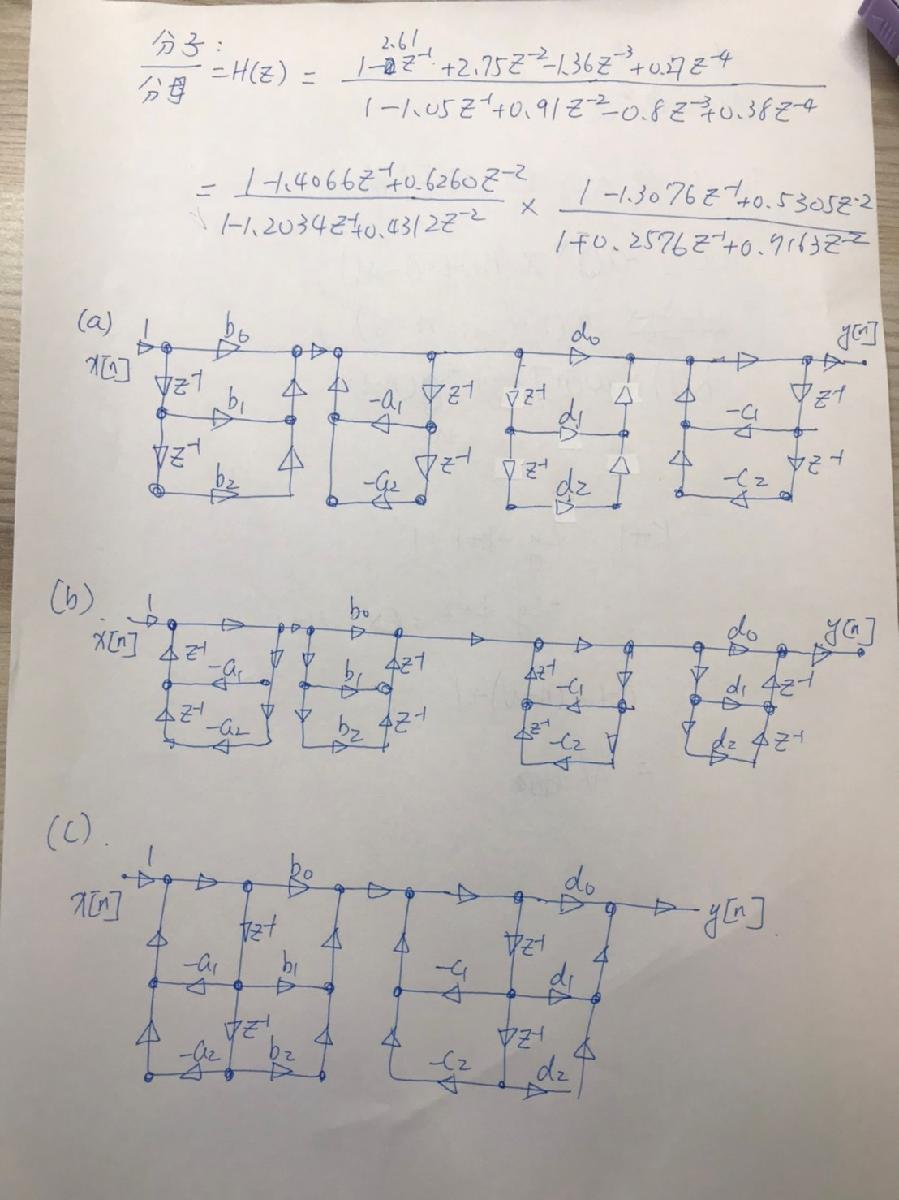

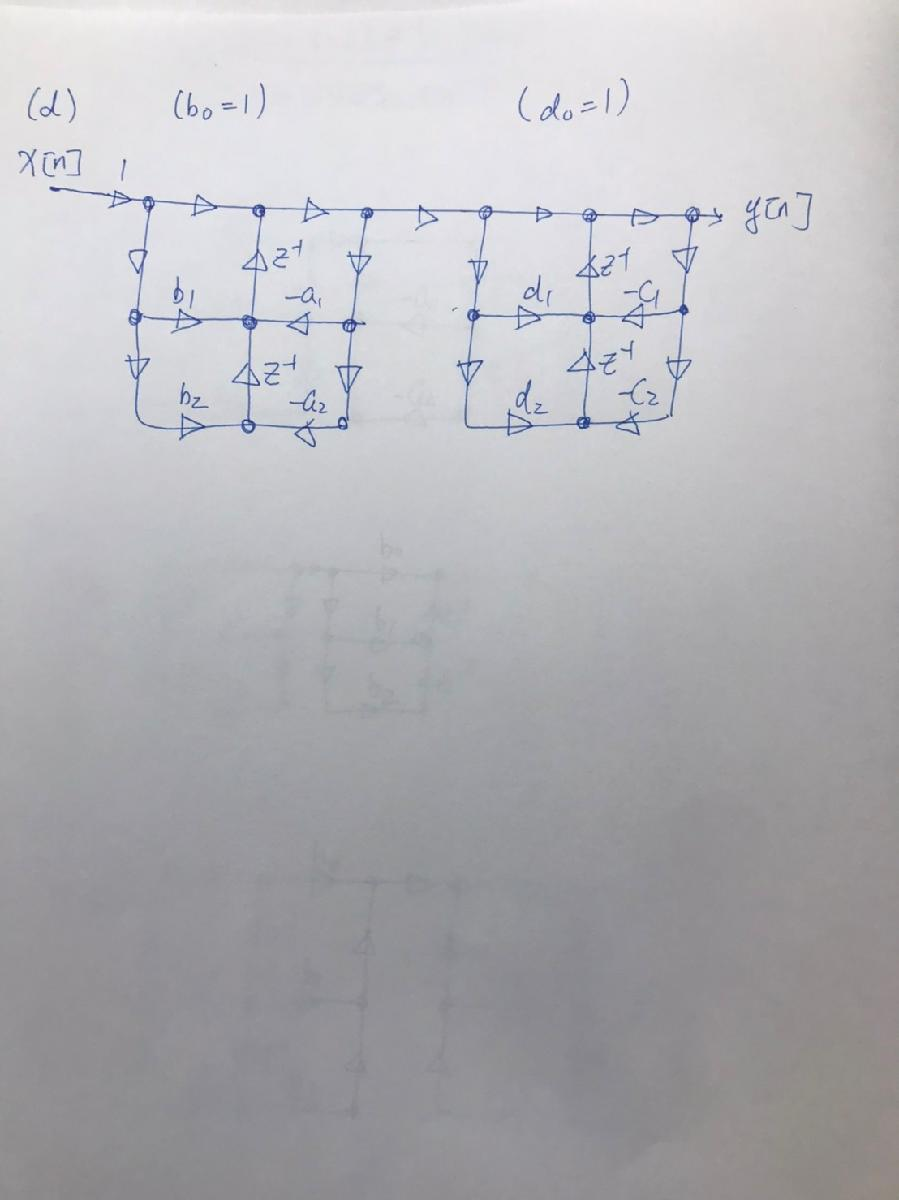

8. (Too hard, skip)